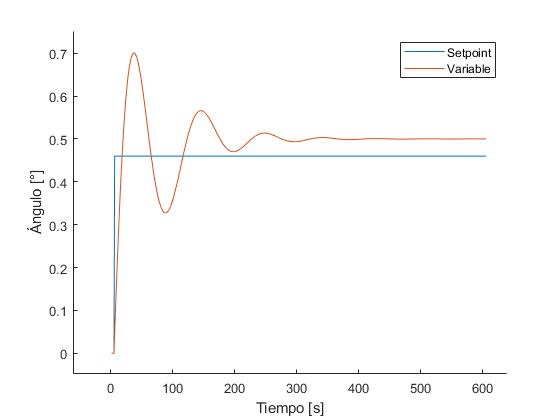

load Datos.mat

hold on
x= [0,0,0,0,0,u];
y= [0,0,0,0,0,deseados];
plot(x)
plot(y)

% plot(ControlOutput)
ylabel("Ángulo [°]");
xlabel("Tiempo [s]");
legend("Setpoint","Variable");

% Parte 2
alfa=1;
% deseados=0;
Aux=0

Aux = 0

% w = rand(1,5)

% w=[0.0003,0.0003,0.0000,-0.9441,1.9433];

for j=1:100000

i=round((length(y)-4)*rand+1);

entradas=[x(1+i:3+i)';y(1+i:2+i)'];
entradas=entradas+(entradas./100).*(rand-0.5);

deseados = y(3+i);

for k=1:5
   [yrk, ecm,w] = feedForwardAdaline(alfa,entradas,w,deseados,1);
% Aux(k)=ecm;
end
Aux(i)=ecm;
[M,I]=sort(Aux,'descend');

y2(j)=yrk;
end









